# DIF ROVNICE 1D - pomocou anonymnej funkcie Nelineárny systém

## EULEROVA METODA

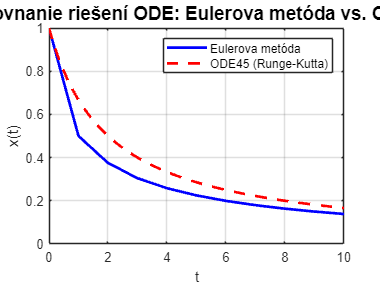

clc, clear, close all

f = @(t,x) -0.5*x^2;

a = 0;
b = 10;
x0 = 1;

% --- Eulerova metóda ---
h1 = 1; % krok
t1 = a:h1:b;
n1 = length(t1);

x1 = zeros(1,n1);
x1(1) = x0;

for i = 1:n1-1
    a1 = f(t1(i),x1(i));
    x1(i+1) = x1(i) + h1*a1;
end

% --- ODE45 ---
[t2, x2] = ode45(f, [a b], x0);

% --- vykreslenie ---
plot(t1, x1, 'b-', 'LineWidth', 2); hold on
plot(t2, x2, 'r--', 'LineWidth', 2);

grid on
xlabel('t')
ylabel('x(t)')
title('Porovnanie riešení ODE: Eulerova metóda vs. ODE45', 'FontSize', 14)

legend('Eulerova metóda', 'ODE45 (Runge-Kutta)')

## Lichobežníkova metóda

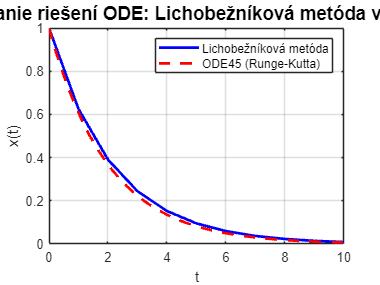

clc, clear, close all

f = @(t,x) -0.5*x;

a = 0;
b = 10;
x0 = 1;

% --- Lichobežníková metóda ---
h1 = 1; % krok
t1 = a:h1:b;
n1 = length(t1);

x1 = zeros(1,n1);
x1(1) = x0;

for i = 1:n1-1
    a1 = f(t1(i), x1(i));
    a2 = f(t1(i)+h1, x1(i)+h1*a1);
    x1(i+1) = x1(i) + (h1/2)*(a1+a2);
end

% --- ODE45 ---
[t2, x2] = ode45(f, [a b], x0);

% --- vykreslenie ---
plot(t1, x1, 'b-', 'LineWidth', 2); hold on
plot(t2, x2, 'r--', 'LineWidth', 2);

grid on
xlabel('t')
ylabel('x(t)')
title('Porovnanie riešení ODE: Lichobežníková metóda vs. ODE45', 'FontSize', 14)

legend('Lichobežníková metóda', 'ODE45 (Runge-Kutta)')

## Runge-Kutta

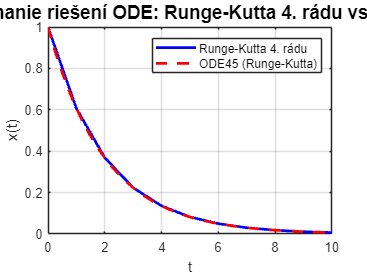

clc, clear, close all

f = @(t,x) -0.5*x;

a = 0;
b = 10;
x0 = 1;

% --- Runge-Kutta 4. rádu ---
h1 = 1; % krok
t1 = a:h1:b;
n1 = length(t1);

x1 = zeros(1,n1);
x1(1) = x0;

for i = 1:n1-1
    a1 = f(t1(i), x1(i));
    a2 = f(t1(i) + h1/2, x1(i) + (h1/2)*a1);
    a3 = f(t1(i) + h1/2, x1(i) + (h1/2)*a2);
    a4 = f(t1(i) + h1, x1(i) + h1*a3);
    x1(i+1) = x1(i) + (h1/6)*(a1 + 2*a2 + 2*a3 + a4);
end

% --- ODE45 ---
[t2, x2] = ode45(f, [a b], x0);

% --- vykreslenie ---
plot(t1, x1, 'b-', 'LineWidth', 2); hold on
plot(t2, x2, 'r--', 'LineWidth', 2);

grid on
xlabel('t')
ylabel('x(t)')
title('Porovnanie riešení ODE: Runge-Kutta 4. rádu vs. ODE45', 'FontSize', 14)

legend('Runge-Kutta 4. rádu', 'ODE45 (Runge-Kutta)')